# Project

hello

addpath('./functions');
addpath('./data');

## Mandatory Part: Methodology

### Loading the MNIST Dataset

Load the dataset

d = load('mnist.mat')

d = struct with fields:
     testX: [10000×784 uint8]
     testY: [7 2 1 0 4 1 4 9 5 9 0 6 9 0 1 5 9 7 3 4 9 6 6 5 4 0 7 4 0 1 3 1 3 4 7 2 7 1 2 1 1 7 4 2 3 5 1 2 4 4 6 3 5 5 6 0 4 1 9 5 7 8 9 3 7 4 6 4 3 0 7 0 2 9 1 7 3 2 9 7 7 6 2 7 8 4 7 3 6 1 3 6 9 3 1 4 1 7 6 9 6 0 5 4 9 9 2 1 9 4 8 7 3 9 7 4 4 4 9 … ]
    trainY: [5 0 4 1 9 2 1 3 1 4 3 5 3 6 1 7 2 8 6 9 4 0 9 1 1 2 4 3 2 7 3 8 6 9 0 5 6 0 7 6 1 8 7 9 3 9 8 5 9 3 3 0 7 4 9 8 0 9 4 1 4 4 6 0 4 5 6 1 0 0 1 7 1 6 3 0 2 1 1 7 9 0 2 6 7 8 3 9 0 4 6 7 4 6 8 0 7 8 3 1 5 7 1 7 1 1 6 3 0 2 9 3 1 1 0 4 9 2 0 … ]
    trainX: [60000×784 uint8]


Visualize images:

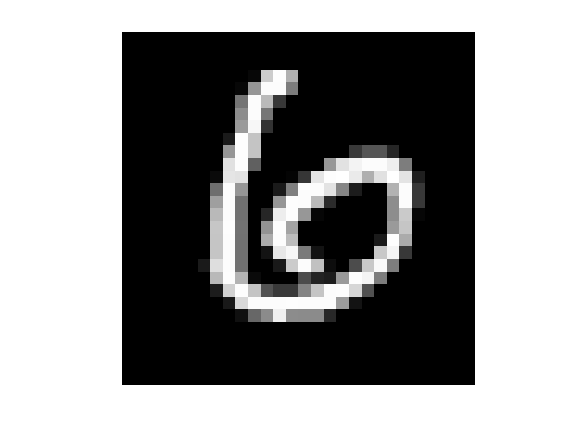

show_digit(d.testX, 12)

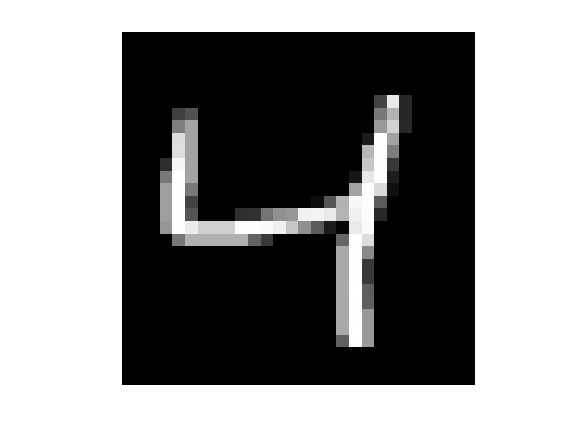

show_digit(d.trainX, 3)

Splitting the training part into training and test sets.

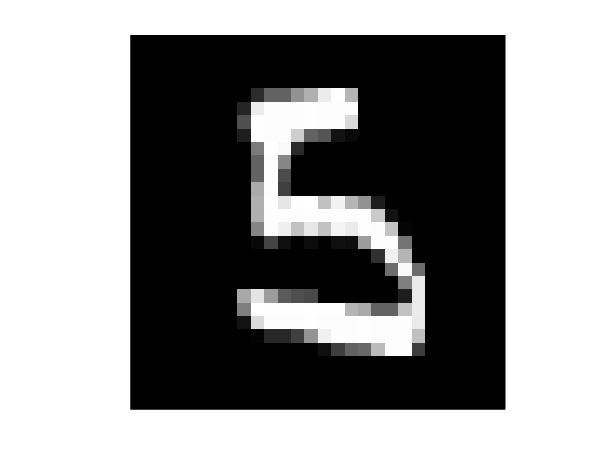

train_perc = 0.8;
% Handle images
x_train = d.trainX(1:int32(size(d.trainX, 1) * train_perc), :)';
x_test = d.trainX(int32(size(d.trainX, 1) * train_perc)+1:end, :)';
x_train = reshape(x_train, [28, 28, 1, size(x_train, 2)]);
x_test = reshape(x_test, [28, 28, 1, size(x_test, 2)]);
x_train = permute(x_train, [2 1 3 4]);
x_test = permute(x_test, [2 1 3 4]);
imshow(x_test(:,:,:, 5))

% Handle labels
y_train = d.trainY(1:int32(length(d.trainY) * train_perc));
y_test = d.trainY(int32(length(d.trainY) * train_perc)+1:end);
y_train = categorical(y_train);
y_test = categorical(y_test);

% Normalize images between 0 and 1
x_train = x_train ./ 255;
x_test = x_test ./ 255;

### FCN

#### Model Definition

"The [segnetLayers](https://www.mathworks.com/help/vision/ref/segnetlayers.html) function creates a U-Net to perform semantic segmentation and the beauty of this type of a network is that it is made up primarily of convolution, relu and batchNormalization layers. Thus, one can pass arbitrary sized inputs during the inference/prediction stage.

This is because a convolutionLayer contains filters of some size (say 3x3) which can be applied on any input irrespective of its size(as mentioned it works well on 200x200 or 1000x1000). The reason why the size needs to be same during training stage is because training happens in batches and each batch must have same size in all dimensions, i.e. [H W C ] dimensions need to be the same for all images during training. But during prediction you are free to pass in an input size smaller or greater than the size used during training."

fcn_layers = fcn_model()

fcn_layers =   10×1 Layer array with layers:

     1   ''   Image Input                  28×28×1 images
     2   ''   Convolution                  128 5×5 convolutions with stride [1  1] and padding 'same'
     3   ''   ReLU                         ReLU
     4   ''   Max Pooling                  2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''   Convolution                  64 5×5 convolutions with stride [1  1] and padding [0  0  0  0]
     6   ''   ReLU                         ReLU
     7   ''   Max Pooling                  2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''   Convolution                  10 5×5 convolutions with stride [1  1] and padding [0  0  0  0]
     9   ''   Softmax                      softmax
    10   ''   Pixel Classification Layer   Cross-entropy loss 

% analyzeNetwork(fcn_layers)

#### Training

Setup th optimizer and train the network.

num_epochs = 2;
% Setup Optimizer
% NOTE: For such a simple dataset, the learning rate drop is not actually
% required (nor actually happening), but I'll keep it for future
% references.
% NOTE: Also ValidationPatience is kinda useless here, but it turn out
% handy in future projects...
% NOTE: Momentum is not available with the Adam optimizer
optimizer = trainingOptions('adam', ...
                            'InitialLearnRate', 2e-3, ...
                            'LearnRateSchedule', 'piecewise', ...
                            'LearnRateDropPeriod', 3, ...
                            'LearnRateDropFactor', 0.5, ...
                            'MaxEpochs', num_epochs, ...
                            'MiniBatchSize', 128, ...
                            'Plots','training-progress', ...
                            'ValidationData', {x_test, y_test}, ...
                            'ValidationPatience', 10);

% Train the network
fcn_net = trainNetwork(x_train, y_train, fcn_layers, optimizer);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:15 |       18.75% |       14.70% |       2.2887 |       2.2677 |          0.0020 |
|       1 |          50 |       00:00:34 |       93.75% |       94.18% |       0.2318 |       0.1983 |          0.0020 |
|       1 |         100 |       00:00:52 |       95.31% |       96.16% |       0.1553 |       0.1208 |          0.0020 |
|       1 |         150 |       00:01:11 |       97.66% |       96.99% |       0.0898 |       0.0985 |          0.0020 |
|       

save('./data/fcn_net.mat', 'fcn_net');

Save or releod network.

load('./data/fcn_net.mat', 'fcn_net');

#### Evaluation

acc_count = nnz(fcn_net.classify(x_test)' == y_test);
acc = acc_count / size(y_test, 2);
disp(['INFO. Network accuracy: ' num2str(acc * 100) '%%'])

INFO. Network accuracy: 98.3667%%


### Scale Space

#### Load Test Image

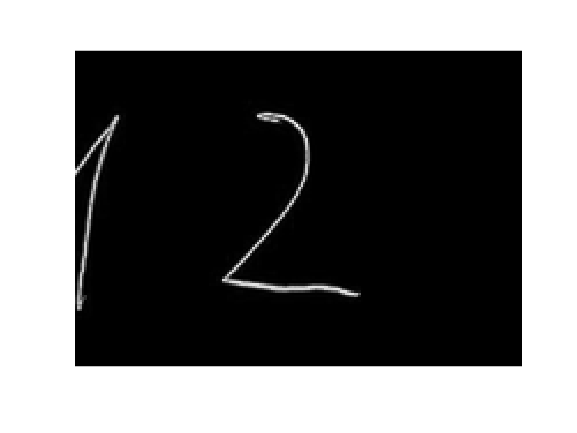

as_grayscale = true;
img = read_image('./data/handwritten.png', as_grayscale);
img = imcomplement(img); % Invert black and white
% img = img ./ max(img, [], 'all'); % Normalize b/w 0 and 1

img_patch = img(782:918, 645:838); % Consider just a portion, for testing
imshow(img_patch)

#### Downscaling (no smoothing)

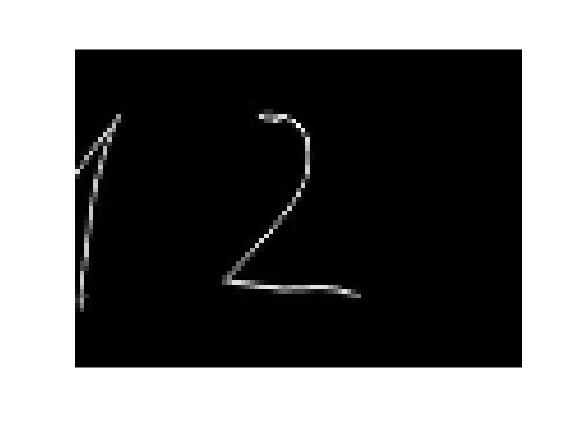

down_factor = 2;
img_down = img_patch(1:down_factor:end, 1:down_factor:end);
imshow(img_down)

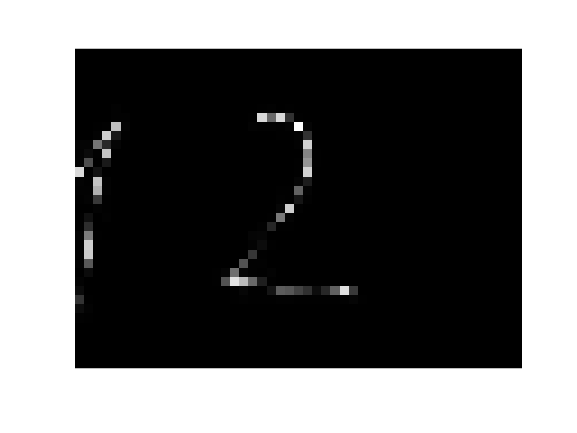

down_factor = 4;
img_down = img_patch(1:down_factor:end, 1:down_factor:end);
imshow(img_down)

#### Smoothing and Downscaling

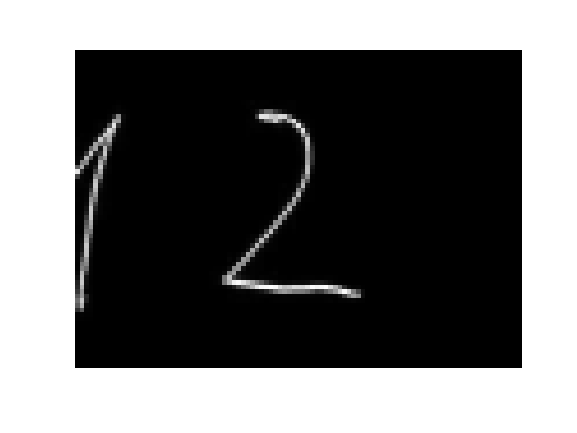

down_factor = 2;
img_smooth = gaussian_filter(img_patch, 0.8);
img_down = img_smooth(1:down_factor:end, 1:down_factor:end);
img_down = img_down ./ max(img_down, [], 'all'); % Normalize b/w 0 and 1
size(img);
size(img_down);
imshow(img_down)

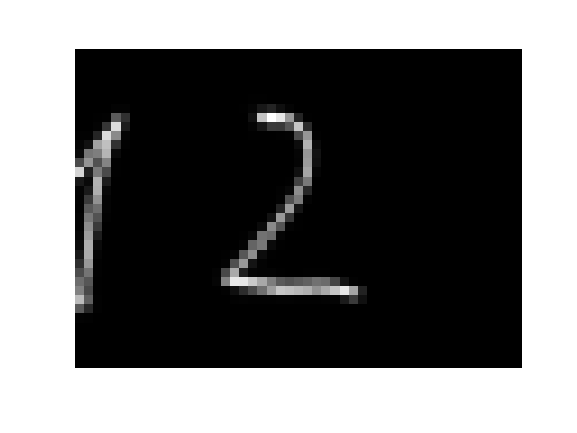

img_down = downscale(img_down, down_factor, down_factor * 0.8);
imshow(img_down)

### Get Boxes from Image

Reload test image

as_grayscale = true;
img = read_image('./data/handwritten.png', as_grayscale);
img = imcomplement(img); % Invert black and white
img = img ./ max(img, [], 'all'); % Normalize b/w 0 and 1
size(img)

ans =         1131        1600


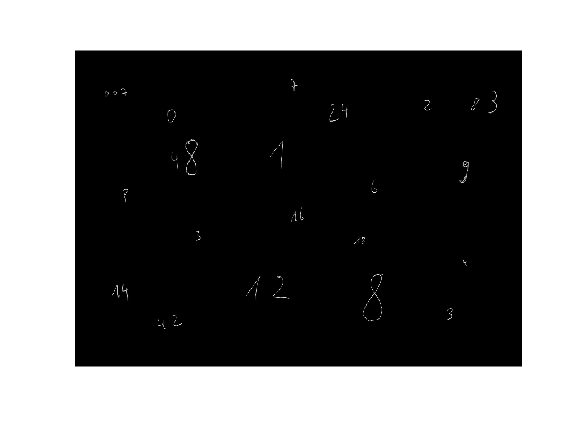

imshow(img)

Loop over image dimensions and get boxes and the actual image patches (to be used as input to the semanticseg() function). No padding. Always starting from top left corner.

If there is no overlapping, then when utilizing IoU, we would need to **combine** the patches with the same classification in a bigger patch. For now, add some overlapping such that some more patches are generated.

box_size = 28;
stride = int32(box_size / 2);
[bboxes, boxes] = get_bboxes(img, box_size, stride);
size(bboxes), size(boxes)

ans =         8927           4


ans =           28          28           1        8927


### Non-Maximum Suppression (NMS)

The NMS happens in two steps:

- Remove all patches with a low confidence score, i.e. with a low maximum probability

- (If no overlapping patches, form the boxes with the same classification)

- Use Intersect Over Union (IoU) to get the most accurate box

TODO: Where do I store the patches? Cell array?

% First get the patches by running the FCN
[~, box_class_probs] = semanticseg(boxes, fcn_net);

#### Step 1:

Get rid of boxes with a low confidence score, i.e. class prob

% Get the max prob from the 10 prob scores and the associated labels
[box_confidence, labels] = max(box_class_probs, [], 2);
confidence_threshold = 0.8;
bboxes_best = bboxes(box_confidence > confidence_threshold, :);
labels = labels(box_confidence > confidence_threshold);
box_scores = box_confidence(box_confidence > confidence_threshold);

#### Step 2:

Identify the best bounding boxes via the MATLAB predefined function.

iou_threshold = 0.3;
[selected_boxes, selected_scores, selected_labels, index] = selectStrongestBboxMulticlass(bboxes_best, box_scores, labels, 'OverlapThreshold', iou_threshold);
size(selected_boxes)

ans =     84     4


size(selected_labels)

ans =     84     1


#### Wrapping NMS into a function

as_grayscale = true;
img = read_image('./data/handwritten.png', as_grayscale);
img = imcomplement(img); % Invert black and white
img = img ./ max(img, [], 'all'); % Normalize b/w 0 and 1
size(img)

ans =         1131        1600


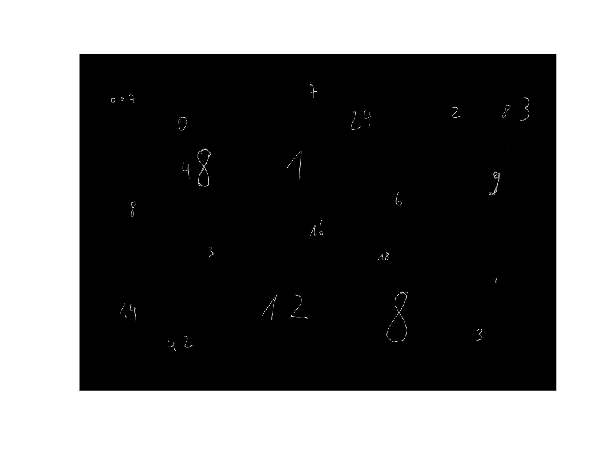

imshow(img)

box_size = 28;
stride = 11;
confidence_threshold = 0.5;
iou_threshold = 0.5;
[boxes, scores, labels] = semanticseg_scalelevel(img, fcn_net, ...
                                                 box_size, stride, ...
                                                 confidence_threshold, ...
                                                 iou_threshold);
disp(['INFO. Number of boxes found: ' num2str(size(boxes, 1))])

INFO. Number of boxes found: 316


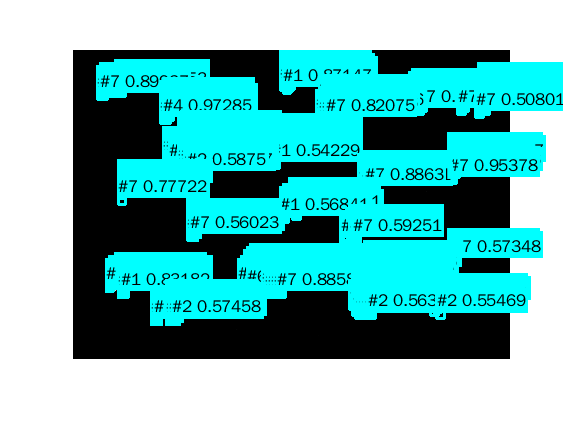

plot_bboxes(img, boxes, labels, scores)

### Scaling and NMS

Must happen at the same scale level

box_size = 28;

down_factor = 2;
stride = 15;
confidence_threshold = 0.8;
iou_threshold = 0.6;
std = 0.8;

img_down = downscale(img, down_factor, std);
size(img_down)

ans =    566   800



[boxes, scores, labels] = nms(img_down, fcn_net, box_size, stride, confidence_threshold, iou_threshold);
disp(['INFO. Number of boxes found: ' num2str(size(boxes, 1))])

INFO. Number of boxes found: 20


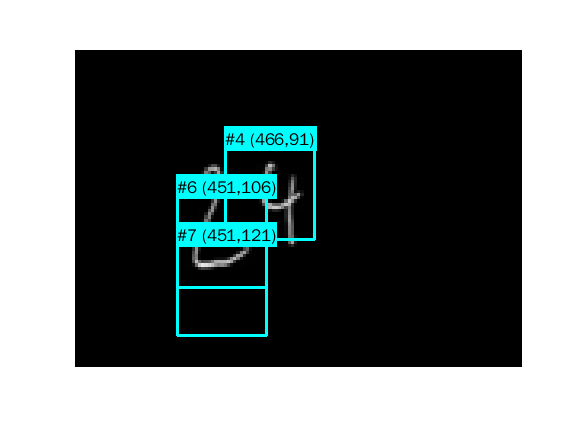

plot_bboxes(img_down, boxes, labels)

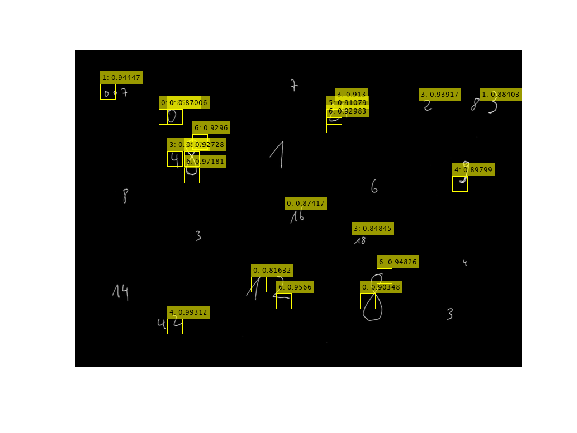

plot_bboxes(img_down, boxes, labels, scores)

find(labels == 0)


ans =

  0×1 empty double column vector



### NMS across Scale Levels

Get all bounding boxes at different scale levels. First check that the bbox definition scales with the scale level: **it does**.

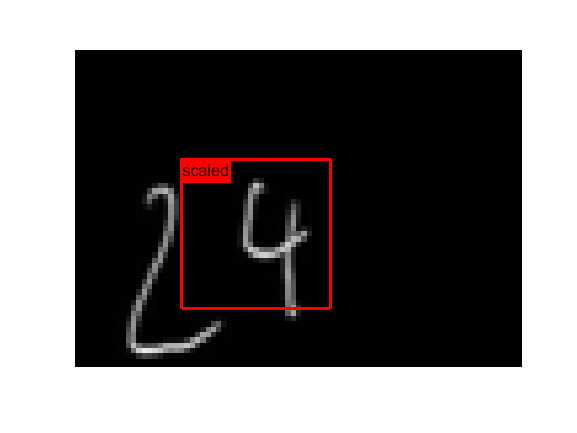

box_size = 28;
down_factor = 2;
std = 0.8;

img_down = downscale(img, down_factor, std);
boxes = zeros(2, 4);
boxes(1, :) = [466, 91, box_size, box_size];
boxes(2, :) = boxes(1, :) * down_factor;

figure, imshow(img_down);
hold on;
showShape('rectangle', round(boxes(1, :)), 'Label', 'scaled', 'Color', 'red');
hold off;

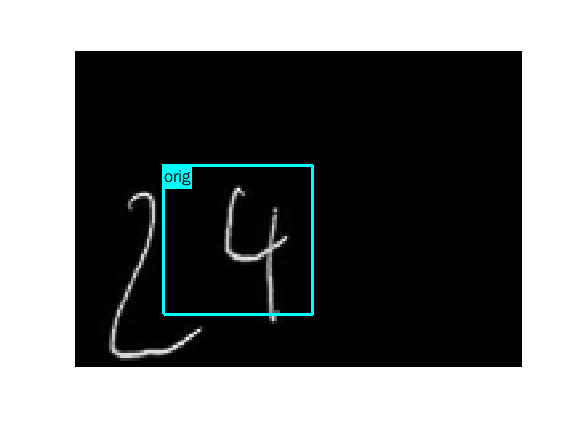


figure, imshow(img);
hold on;
showShape('rectangle', round(boxes(2, :)), 'Label', 'orig', 'Color', 'cyan');
hold off;

% Fixed parameters at all scale levels
box_size = 28;
std = 0.8;
confidence_threshold = 0.7;
iou_threshold = 0.3;
% Scale levels and changing parameters
downscale_levels = [1, 2, 3, 4, 5, 6, 7, 8, 1/2, 1/3];
strides = [5, 5, 5, 5, 5, 5, 3, 5, 11, 15];
bboxes = [];
scores = [];
labels = [];
for n = 1:length(downscale_levels)
    t = downscale_levels(n);
    confidence_threshold = confidence_threshold - t * 0.01;
    stride = strides(n);
    img_down = downscale(img, t, std);
    [b, s, l] = semanticseg_scalelevel(img_down, ...
                                       fcn_net, box_size, stride, ...
                                       confidence_threshold, iou_threshold);
    disp(['INFO. Number of boxes found at level ' num2str(t) ': ' num2str(size(b, 1))])
    if size(b, 1) > 0
        if n == 1
            bboxes = round(b * t);
            scores = s;
            labels = l;
        else
            bboxes = vertcat(bboxes, round(b * t));
            scores = vertcat(scores, s);
            labels = vertcat(labels, l);
        end
    end
end

num bboxes: 49


INFO. Number of boxes found at level 1: 49


num bboxes: 31


INFO. Number of boxes found at level 2: 31


num bboxes: 6


INFO. Number of boxes found at level 3: 6


num bboxes: 1


INFO. Number of boxes found at level 4: 1


num bboxes: 0


INFO. Number of boxes found at level 5: 0


num bboxes: 0


INFO. Number of boxes found at level 6: 0


num bboxes: 0


INFO. Number of boxes found at level 7: 0


num bboxes: 1


INFO. Number of boxes found at level 8: 1


num bboxes: 4


INFO. Number of boxes found at level 0.5: 4


num bboxes: 0


INFO. Number of boxes found at level 0.33333: 0


disp(['INFO. Total boxes found: ' num2str(size(bboxes, 1))])

INFO. Total boxes found: 92


Use IoU as NMS once we found all boxes at all desired levels.

iou_threshold = 0.8;
[final_boxes, final_scores, final_labels, ~] = ...
        selectStrongestBboxMulticlass(bboxes, scores, labels, ...,
        'OverlapThreshold', 1- iou_threshold);
disp(['INFO. Final boxes found: ' num2str(size(final_boxes, 1))])

INFO. Final boxes found: 152


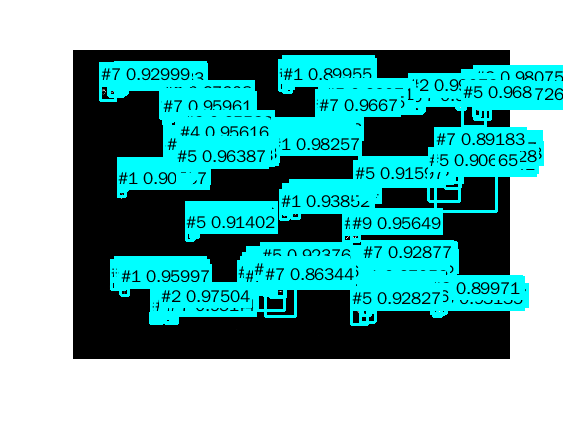

plot_bboxes(img, final_boxes, final_labels, final_scores)

The function *bboxOverlapRatio()* returns a matrix of IoU ratios. If applied on the boxes, it will give us the IoU of all the **pairs** of boxes. Naturally, the main diagonal will be all 1s since each pair perfectly overlaps with itself, whereas the overall matrix will be symmetrical. That's why we only consider the bottom half of it through the *tril(..., -1)* function.

iou_threshold = 0.2;
size(bboxes, 1)

ans = 92

[final_boxes, final_scores, final_labels] = nms(bboxes, ...
        scores, labels, iou_threshold);

num bboxes: 60


size(final_boxes, 1)

ans = 60

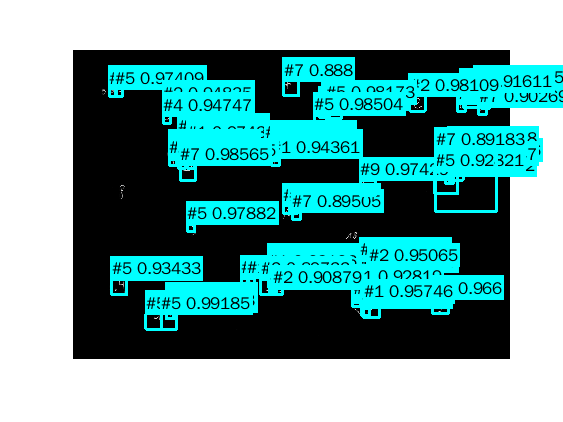

plot_bboxes(img, final_boxes, final_labels, final_scores)

### Wrapping all together in a single function

% Fixed parameters at all scale levels
box_size = 28;
std = 0.8;
confidence_threshold = 0.9;
iou_level_threshold = 0.3;
iou_final_threshold = 0.02;
% Scale levels and changing parameters
downscale_levels = [1, 2, 3, 4, 5, 6, 1/1.5, 1/2, 1/3];
strides = [15, 11, 11, 7, 7, 7, 7, 11, 11];

[final_boxes, final_scores, final_labels] = semanticseg_img(...
        img, fcn_net, box_size, strides, downscale_levels, ...
        confidence_threshold, iou_level_threshold, iou_final_threshold)

INFO. Number of boxes found at level 1: 32
INFO. Number of boxes found at level 2: 13
INFO. Number of boxes found at level 3: 3
INFO. Number of boxes found at level 4: 1
INFO. Number of boxes found at level 5: 0
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 51
INFO. Number of boxes found at level 0.5: 4
INFO. Number of boxes found at level 0.33333: 0
INFO. Total boxes found: 47


final_boxes =          331         241          28          28
         901         241          28          28
         691         361          28          28
         391         391          28          28
         421         421          28          28
         391         436          28          28
        1366         451          28          28
        1051         466          28          28
         166         481          28          28
         166         511          28          28


final_scores = 47×1 single column vector
    0.9696
    0.9290
    0.9505
    0.9861
    0.9954
    0.8964
    0.9189
    0.9504
    0.9115
    0.9079


final_labels =      4
     5
     1
     1
     1
     5
     2
     1
     2
     1


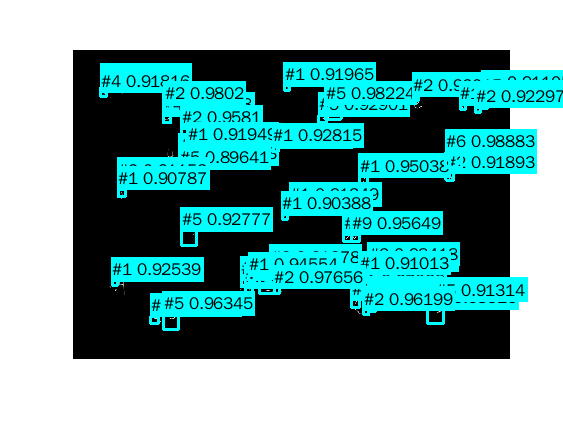

plot_bboxes(img, final_boxes, final_labels, final_scores)

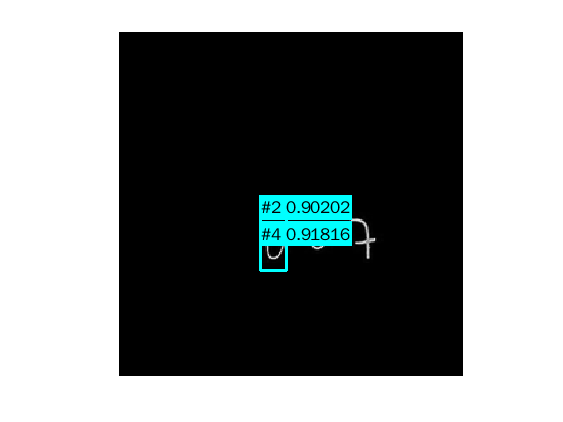

plot_bboxes(img(1:250, 1:250), final_boxes, final_labels, final_scores)

## Mandatory Part: Evaluation

Load gold annotations

anno = load('anno.mat').anno;
anno.bbox_annotations

ans = 4×10 table
      digit_0         digit_1         digit_2            digit_3              digit_4              digit_5              digit_6           digit_7            digit_8              digit_9      
    ____________    ____________    ____________    _________________    _________________    _________________    _________________    ____________    _________________    __________________

    {4×4 double}    {2×4 double}    {2×4 double}    {2×4 double     }    {[141 117 69 65]}    {[709 459 73 62]}    {[705 127 87 81]}    {2×4 double}    {[284 353 28 29]}    {[ 689 298 40 41]}
    {4×4 double}    {2×4 double}    {2×4 double}    {2×4 double   

anno.image_filenames

ans = 4×1 cell array
    {'computer_generated.png'        }
    {'computer_generated_rotated.png'}
    {'handwritten.png'               }
    {'handwritten_rotated.png'       }


digit_annotations = anno.bbox_annotations(3, :)

digit_annotations = 1×10 table
      digit_0         digit_1         digit_2         digit_3         digit_4         digit_5         digit_6         digit_7         digit_8            digit_9      
    ____________    ____________    ____________    ____________    ____________    ____________    ____________    ____________    ____________    __________________

    {3×4 double}    {5×4 double}    {4×4 double}    {3×4 double}    {5×4 double}    {0×0 double}    {2×4 double}    {2×4 double}    {5×4 double}    {[1353 390 83 92]}


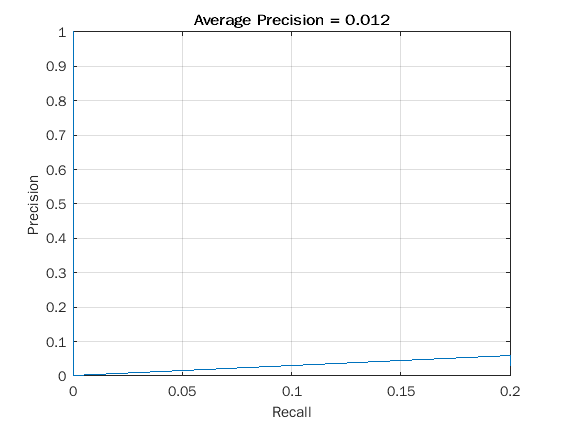

[average_precision, recall, precision] = eval_semanticseg(...
        digit_annotations, final_boxes, final_scores, final_labels);
% plot(cell2mat(recall), cell2mat(precision))
average_precision;
recall;
precision;
digit = 2;
ap = average_precision(digit);
r = (cell2mat(recall(digit, :)));
p = (cell2mat(precision(digit, :)));
figure, plot(r, p)
grid on
title(sprintf('Average Precision = %.3f', ap))
xlabel('Recall')
ylabel('Precision')

    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 41
INFO. Number of boxes found at level 2: 27
INFO. Number of boxes found at level 3: 23
INFO. Number of boxes found at level 4: 21
INFO. Number of boxes found at level 5: 11
INFO. Number of boxes found at level 6: 4
INFO. Number of boxes found at level 0.66667: 56
INFO. Number of boxes found at level 0.5: 10
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 193
INFO. Total boxes found: 168


average_precision =     0.2500
    0.5000
    0.5000
         0
         0
    0.3333
         0
    0.0738
         0
         0


recall = 10×1 cell array
    { 5×1 double}
    {32×1 double}
    {46×1 double}
    {[        0]}
    {[        0]}
    {33×1 double}
    {10×1 double}
    {43×1 double}
    {[        0]}
    { 6×1 double}


precision = 10×1 cell array
    { 5×1 double}
    {32×1 double}
    {46×1 double}
    {[        1]}
    {[        1]}
    {33×1 double}
    {10×1 double}
    {43×1 double}
    {[        1]}
    { 6×1 double}


Average mAP across digits: 0.16571


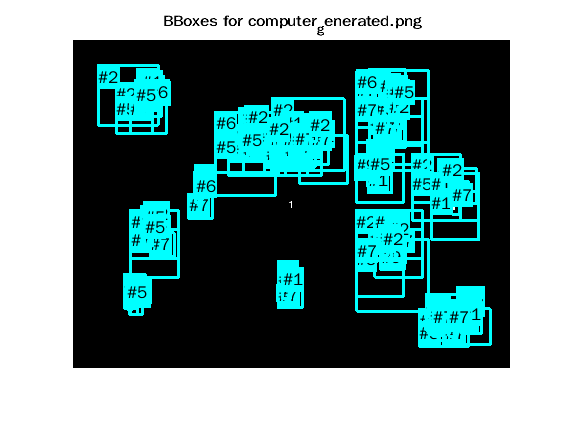

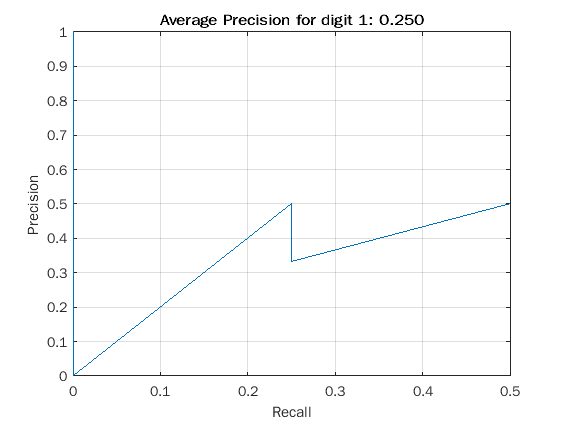

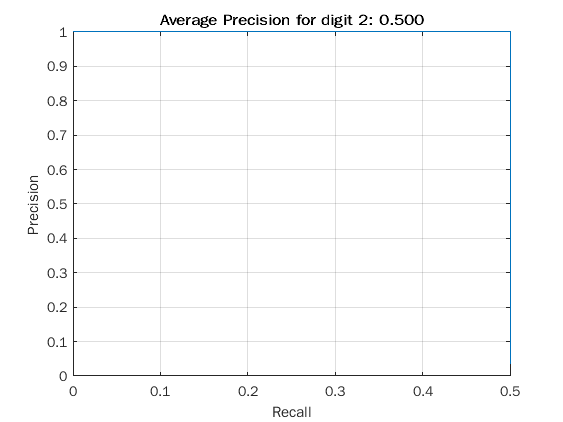

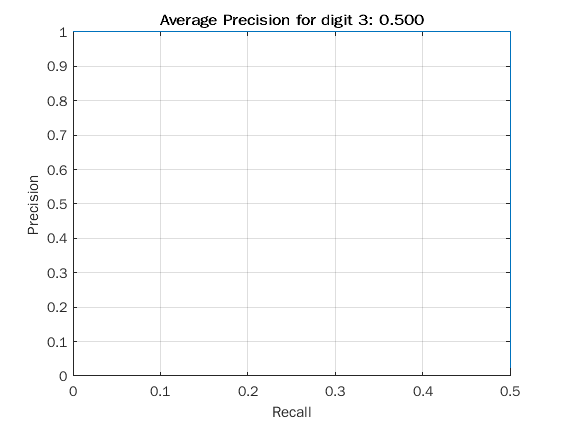

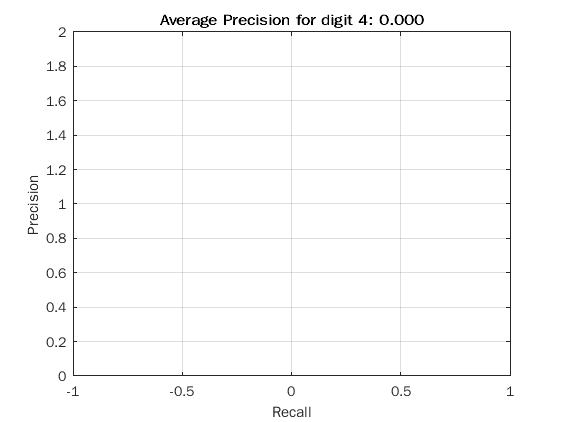

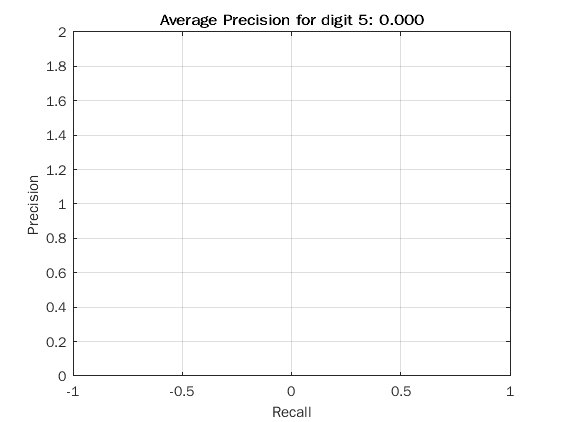

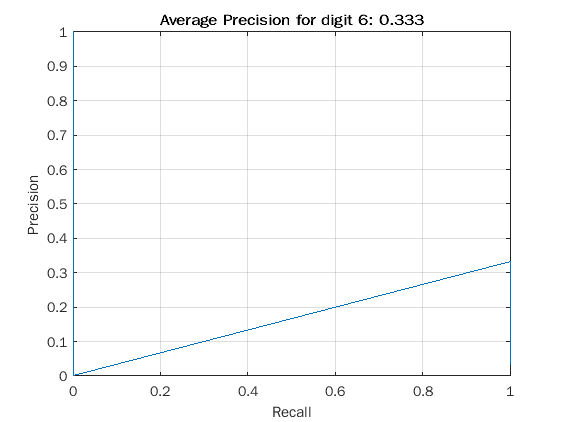

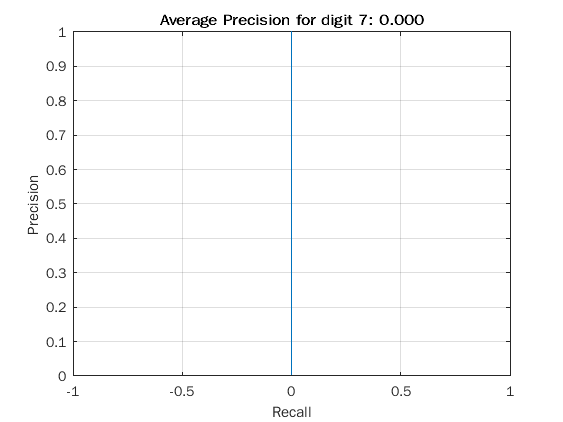

    "Semantic Segmentation on image: "    "handwritten.png"



INFO. Number of boxes found at level 1: 50
INFO. Number of boxes found at level 2: 17
INFO. Number of boxes found at level 3: 9
INFO. Number of boxes found at level 4: 4
INFO. Number of boxes found at level 5: 0
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 87
INFO. Number of boxes found at level 0.5: 13
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 180
INFO. Total boxes found: 170


average_precision =          0
    0.0262
    0.0278
         0
    0.0667
         0
         0
         0
         0
         0


recall = 10×1 cell array
    { 2×1 double}
    {89×1 double}
    {33×1 double}
    {[        0]}
    { 4×1 double}
    {[        0]}
    { 3×1 double}
    {24×1 double}
    {[        0]}
    { 3×1 double}


precision = 10×1 cell array
    { 2×1 double}
    {89×1 double}
    {33×1 double}
    {[        1]}
    { 4×1 double}
    {[        1]}
    { 3×1 double}
    {24×1 double}
    {[        1]}
    { 3×1 double}


Average mAP across digits: 0.012063


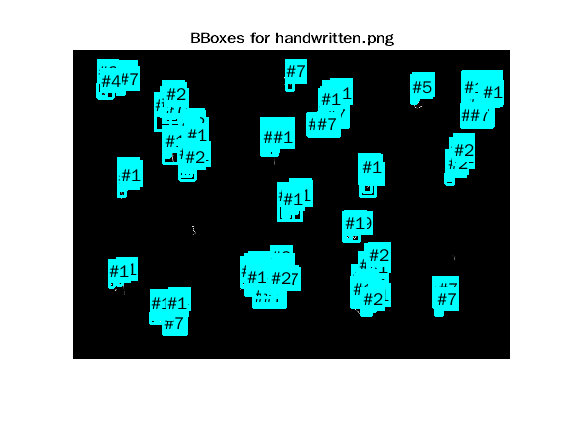

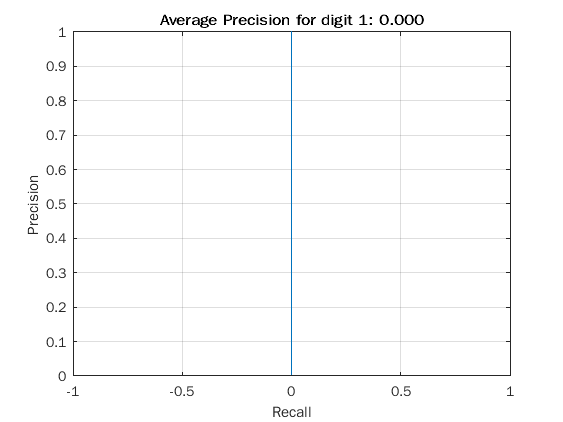

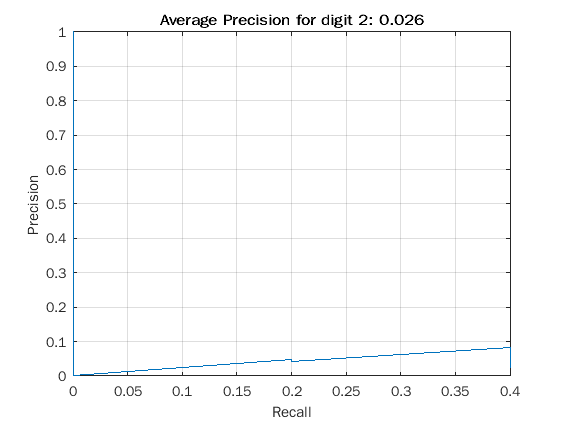

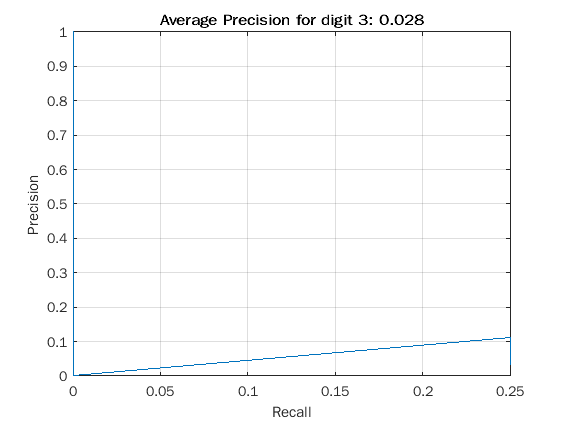

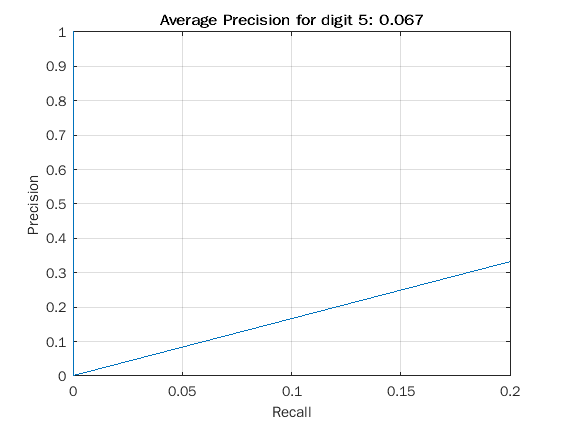

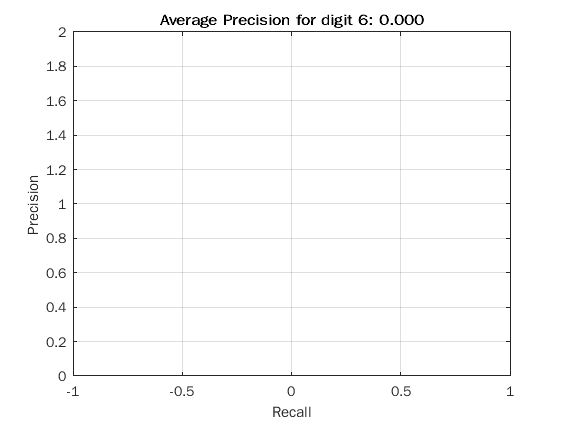

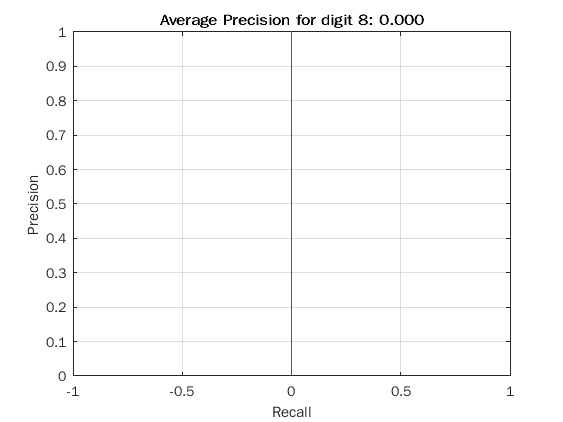

as_grayscale = true;
% Fixed parameters at all scale levels
box_size = 28;
std = 0.8;
confidence_threshold = 0.8;
iou_level_threshold = 0.5;
iou_final_threshold = 0.5;
% Scale levels and changing parameters
downscale_levels = [1, 2, 3, 4, 5, 6, 1/1.5, 1/2, 1/3, 1/4];
strides = [15, 15, 11, 11, 11, 11, 11, 7, 11, 15];

for n = [1, 3] % 1:length(anno.image_filenames)
    disp(['Semantic Segmentation on image: ' string(anno.image_filenames(n))])
    % Load image and normalize it
    img = read_image('./data/' + string(anno.image_filenames(n)), as_grayscale);
    img = imcomplement(img); % Invert black and white
    img = img ./ max(img, [], 'all'); % Normalize b/w 0 and 1
    % Run Semantic Segmentation
    [final_boxes, final_scores, final_labels] = semanticseg_img(...
        img, fcn_net, box_size, strides, downscale_levels, ...
        confidence_threshold, iou_level_threshold, iou_final_threshold);
    % Evaluate system
    digit_annotations = anno.bbox_annotations(n, :);
    [average_precision, recall, precision] = eval_semanticseg(digit_annotations, ...
        final_boxes, final_scores, final_labels);
    % Plotting
    average_precision, recall, precision
    disp(['Average mAP across digits: ' num2str(mean(average_precision))])
    figure, plot_bboxes(img, final_boxes, final_labels, final_scores)
    title(sprintf('BBoxes for %s', string(anno.image_filenames(n))));
    for digit = 1:10
        ap = average_precision(digit);
        r = (cell2mat(recall(digit, :)));
        p = (cell2mat(precision(digit, :)));
        figure, plot(r, p)
        grid on
        title(sprintf('Average Precision for digit %d: %.3f', digit, ap))
        xlabel('Recall')
        ylabel('Precision')
    end
end

iou_level_threshold: 0.3


iou_final_threshold: 0.3


stride_size: 5


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 114
INFO. Number of boxes found at level 2: 84
INFO. Number of boxes found at level 3: 46
INFO. Number of boxes found at level 4: 32
INFO. Number of boxes found at level 5: 13
INFO. Number of boxes found at level 6: 9
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 314
INFO. Total boxes found: 103


Average mAP across digits: 0.5625


iou_level_threshold: 0.3


iou_final_threshold: 0.3


stride_size: 11


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 41
INFO. Number of boxes found at level 2: 29
INFO. Number of boxes found at level 3: 14
INFO. Number of boxes found at level 4: 12
INFO. Number of boxes found at level 5: 4
INFO. Number of boxes found at level 6: 1
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 117
INFO. Total boxes found: 70


Average mAP across digits: 0.44583


iou_level_threshold: 0.3


iou_final_threshold: 0.3


stride_size: 15


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 20
INFO. Number of boxes found at level 2: 20
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 6
INFO. Number of boxes found at level 5: 3
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 72
INFO. Total boxes found: 47


Average mAP across digits: 0.15583


iou_level_threshold: 0.3


iou_final_threshold: 0.4


stride_size: 5


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 114
INFO. Number of boxes found at level 2: 84
INFO. Number of boxes found at level 3: 46
INFO. Number of boxes found at level 4: 32
INFO. Number of boxes found at level 5: 13
INFO. Number of boxes found at level 6: 9
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 314
INFO. Total boxes found: 145


Average mAP across digits: 0.63667


iou_level_threshold: 0.3


iou_final_threshold: 0.4


stride_size: 11


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 41
INFO. Number of boxes found at level 2: 29
INFO. Number of boxes found at level 3: 14
INFO. Number of boxes found at level 4: 12
INFO. Number of boxes found at level 5: 4
INFO. Number of boxes found at level 6: 1
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 117
INFO. Total boxes found: 74


Average mAP across digits: 0.44464


iou_level_threshold: 0.3


iou_final_threshold: 0.4


stride_size: 15


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 20
INFO. Number of boxes found at level 2: 20
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 6
INFO. Number of boxes found at level 5: 3
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 72
INFO. Total boxes found: 61


Average mAP across digits: 0.15298


iou_level_threshold: 0.3


iou_final_threshold: 0.5


stride_size: 5


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 114
INFO. Number of boxes found at level 2: 84
INFO. Number of boxes found at level 3: 46
INFO. Number of boxes found at level 4: 32
INFO. Number of boxes found at level 5: 13
INFO. Number of boxes found at level 6: 9
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 314
INFO. Total boxes found: 203


Average mAP across digits: 0.64528


average_precision =     0.2917
    0.5000
    0.2111
    1.0000
    1.0000
    1.0000
    1.0000
    0.4500
    1.0000
         0


recall = 10×1 cell array
    { 7×1 double}
    {33×1 double}
    {48×1 double}
    { 3×1 double}
    { 7×1 double}
    {46×1 double}
    { 9×1 double}
    {42×1 double}
    { 3×1 double}
    {15×1 double}


precision = 10×1 cell array
    { 7×1 double}
    {33×1 double}
    {48×1 double}
    { 3×1 double}
    { 7×1 double}
    {46×1 double}
    { 9×1 double}
    {42×1 double}
    { 3×1 double}
    {15×1 double}


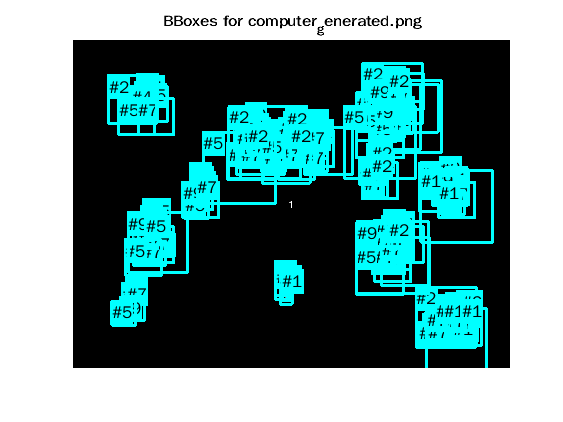

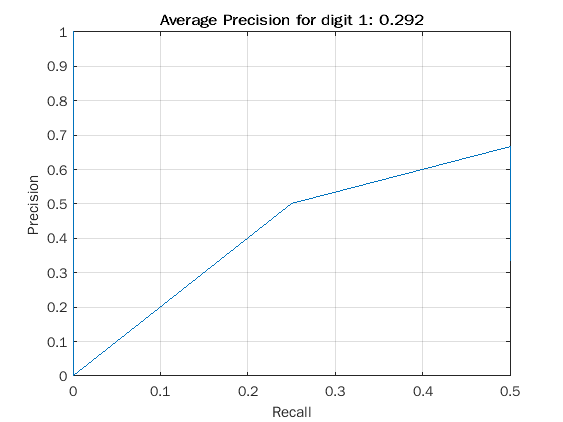

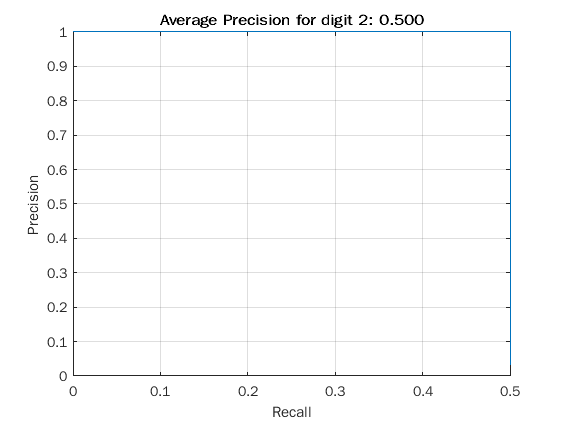

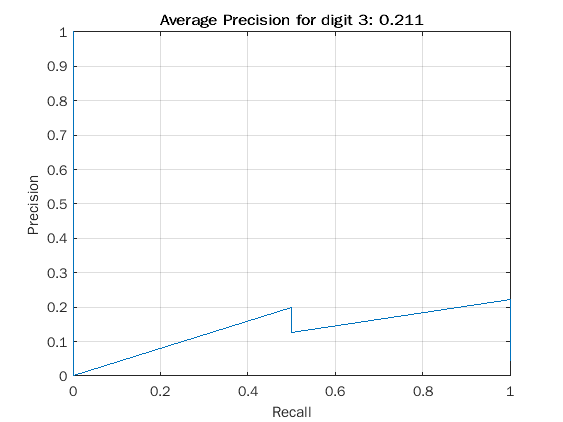

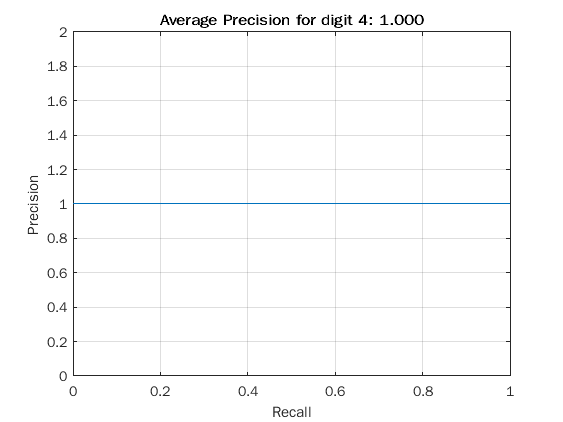

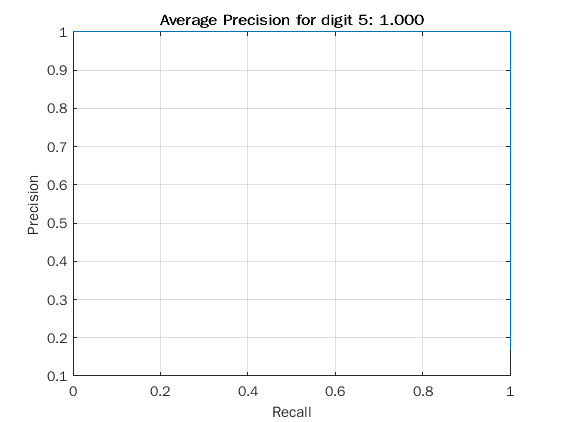

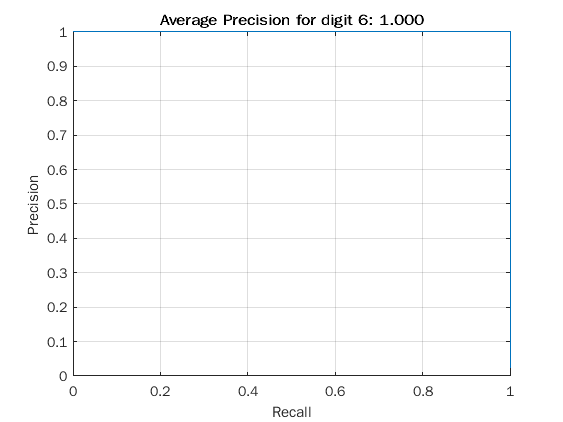

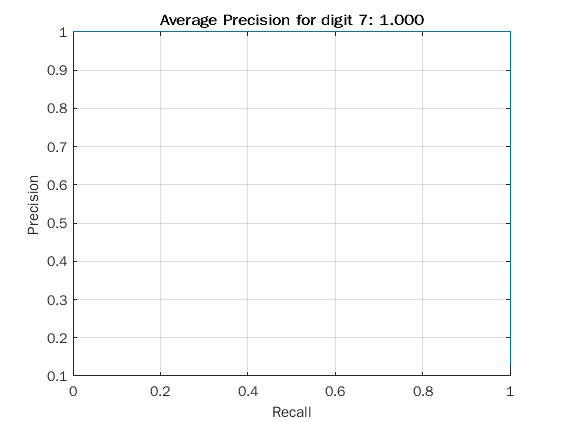

    "Semantic Segmentation on image: "    "handwritten.png"



INFO. Number of boxes found at level 1: 138
INFO. Number of boxes found at level 2: 63
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 5
INFO. Number of boxes found at level 5: 0
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 15
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 228
INFO. Total boxes found: 205


Average mAP across digits: 0.12361


iou_level_threshold: 0.3


iou_final_threshold: 0.5


stride_size: 11


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 41
INFO. Number of boxes found at level 2: 29
INFO. Number of boxes found at level 3: 14
INFO. Number of boxes found at level 4: 12
INFO. Number of boxes found at level 5: 4
INFO. Number of boxes found at level 6: 1
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 117
INFO. Total boxes found: 108


Average mAP across digits: 0.51407


iou_level_threshold: 0.3


iou_final_threshold: 0.5


stride_size: 15


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 20
INFO. Number of boxes found at level 2: 20
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 6
INFO. Number of boxes found at level 5: 3
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 72
INFO. Total boxes found: 71


Average mAP across digits: 0.15139


iou_level_threshold: 0.4


iou_final_threshold: 0.3


stride_size: 5


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 121
INFO. Number of boxes found at level 2: 94
INFO. Number of boxes found at level 3: 49
INFO. Number of boxes found at level 4: 34
INFO. Number of boxes found at level 5: 13
INFO. Number of boxes found at level 6: 9
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 336
INFO. Total boxes found: 108


Average mAP across digits: 0.5625


iou_level_threshold: 0.4


iou_final_threshold: 0.3


stride_size: 11


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 41
INFO. Number of boxes found at level 2: 29
INFO. Number of boxes found at level 3: 14
INFO. Number of boxes found at level 4: 12
INFO. Number of boxes found at level 5: 4
INFO. Number of boxes found at level 6: 1
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 117
INFO. Total boxes found: 70


Average mAP across digits: 0.44583


iou_level_threshold: 0.4


iou_final_threshold: 0.3


stride_size: 15


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 22
INFO. Number of boxes found at level 2: 20
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 6
INFO. Number of boxes found at level 5: 3
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 74
INFO. Total boxes found: 47


Average mAP across digits: 0.15583


iou_level_threshold: 0.4


iou_final_threshold: 0.4


stride_size: 5


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 121
INFO. Number of boxes found at level 2: 94
INFO. Number of boxes found at level 3: 49
INFO. Number of boxes found at level 4: 34
INFO. Number of boxes found at level 5: 13
INFO. Number of boxes found at level 6: 9
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 336
INFO. Total boxes found: 149


Average mAP across digits: 0.64222


iou_level_threshold: 0.4


iou_final_threshold: 0.4


stride_size: 11


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 41
INFO. Number of boxes found at level 2: 29
INFO. Number of boxes found at level 3: 14
INFO. Number of boxes found at level 4: 12
INFO. Number of boxes found at level 5: 4
INFO. Number of boxes found at level 6: 1
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 117
INFO. Total boxes found: 74


Average mAP across digits: 0.44464


iou_level_threshold: 0.4


iou_final_threshold: 0.4


stride_size: 15


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 22
INFO. Number of boxes found at level 2: 20
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 6
INFO. Number of boxes found at level 5: 3
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 74
INFO. Total boxes found: 63


Average mAP across digits: 0.15298


iou_level_threshold: 0.4


iou_final_threshold: 0.5


stride_size: 5


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 121
INFO. Number of boxes found at level 2: 94
INFO. Number of boxes found at level 3: 49
INFO. Number of boxes found at level 4: 34
INFO. Number of boxes found at level 5: 13
INFO. Number of boxes found at level 6: 9
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 336
INFO. Total boxes found: 213


Average mAP across digits: 0.64528


    "Semantic Segmentation on image: "    "handwritten.png"



INFO. Number of boxes found at level 1: 158
INFO. Number of boxes found at level 2: 63
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 5
INFO. Number of boxes found at level 5: 0
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 17
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 250
INFO. Total boxes found: 226


Average mAP across digits: 0.12295


iou_level_threshold: 0.4


iou_final_threshold: 0.5


stride_size: 11


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 41
INFO. Number of boxes found at level 2: 29
INFO. Number of boxes found at level 3: 14
INFO. Number of boxes found at level 4: 12
INFO. Number of boxes found at level 5: 4
INFO. Number of boxes found at level 6: 1
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 117
INFO. Total boxes found: 108


Average mAP across digits: 0.51407


iou_level_threshold: 0.4


iou_final_threshold: 0.5


stride_size: 15


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 22
INFO. Number of boxes found at level 2: 20
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 6
INFO. Number of boxes found at level 5: 3
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 74
INFO. Total boxes found: 73


Average mAP across digits: 0.15139


iou_level_threshold: 0.5


iou_final_threshold: 0.3


stride_size: 5


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 132
INFO. Number of boxes found at level 2: 98
INFO. Number of boxes found at level 3: 52
INFO. Number of boxes found at level 4: 36
INFO. Number of boxes found at level 5: 14
INFO. Number of boxes found at level 6: 10
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 358
INFO. Total boxes found: 106


Average mAP across digits: 0.5625


iou_level_threshold: 0.5


iou_final_threshold: 0.3


stride_size: 11


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 47
INFO. Number of boxes found at level 2: 30
INFO. Number of boxes found at level 3: 14
INFO. Number of boxes found at level 4: 13
INFO. Number of boxes found at level 5: 4
INFO. Number of boxes found at level 6: 1
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 125
INFO. Total boxes found: 71


Average mAP across digits: 0.44583


iou_level_threshold: 0.5


iou_final_threshold: 0.3


stride_size: 15


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 22
INFO. Number of boxes found at level 2: 20
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 6
INFO. Number of boxes found at level 5: 3
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 74
INFO. Total boxes found: 47


Average mAP across digits: 0.15583


iou_level_threshold: 0.5


iou_final_threshold: 0.4


stride_size: 5


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 132
INFO. Number of boxes found at level 2: 98
INFO. Number of boxes found at level 3: 52
INFO. Number of boxes found at level 4: 36
INFO. Number of boxes found at level 5: 14
INFO. Number of boxes found at level 6: 10
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 358
INFO. Total boxes found: 151


Average mAP across digits: 0.64222


iou_level_threshold: 0.5


iou_final_threshold: 0.4


stride_size: 11


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 47
INFO. Number of boxes found at level 2: 30
INFO. Number of boxes found at level 3: 14
INFO. Number of boxes found at level 4: 13
INFO. Number of boxes found at level 5: 4
INFO. Number of boxes found at level 6: 1
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 125
INFO. Total boxes found: 75


Average mAP across digits: 0.45131


iou_level_threshold: 0.5


iou_final_threshold: 0.4


stride_size: 15


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 22
INFO. Number of boxes found at level 2: 20
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 6
INFO. Number of boxes found at level 5: 3
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 74
INFO. Total boxes found: 63


Average mAP across digits: 0.15298


iou_level_threshold: 0.5


iou_final_threshold: 0.5


stride_size: 5


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 132
INFO. Number of boxes found at level 2: 98
INFO. Number of boxes found at level 3: 52
INFO. Number of boxes found at level 4: 36
INFO. Number of boxes found at level 5: 14
INFO. Number of boxes found at level 6: 10
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 358
INFO. Total boxes found: 227


Average mAP across digits: 0.64528


    "Semantic Segmentation on image: "    "handwritten.png"



INFO. Number of boxes found at level 1: 170
INFO. Number of boxes found at level 2: 65
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 5
INFO. Number of boxes found at level 5: 0
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 17
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 264
INFO. Total boxes found: 240


Average mAP across digits: 0.1228


iou_level_threshold: 0.5


iou_final_threshold: 0.5


stride_size: 11


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 47
INFO. Number of boxes found at level 2: 30
INFO. Number of boxes found at level 3: 14
INFO. Number of boxes found at level 4: 13
INFO. Number of boxes found at level 5: 4
INFO. Number of boxes found at level 6: 1
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 125
INFO. Total boxes found: 116


Average mAP across digits: 0.51407


iou_level_threshold: 0.5


iou_final_threshold: 0.5


stride_size: 15


    "Semantic Segmentation on image: "    "computer_generated.png"



INFO. Number of boxes found at level 1: 22
INFO. Number of boxes found at level 2: 20
INFO. Number of boxes found at level 3: 7
INFO. Number of boxes found at level 4: 6
INFO. Number of boxes found at level 5: 3
INFO. Number of boxes found at level 6: 0
INFO. Number of boxes found at level 0.66667: 16
INFO. Number of boxes found at level 0.5: 0
INFO. Number of boxes found at level 0.33333: 0
INFO. Number of boxes found at level 0.25: 0
INFO. Bboxes found in scale space: 74
INFO. Total boxes found: 73


Average mAP across digits: 0.15139


as_grayscale = true;
% Fixed parameters at all scale levels
box_size = 28;
std = 0.8;
confidence_threshold = 0.9;
% iou_level_threshold = 0.5;
% iou_final_threshold = 0.5;
% Scale levels and changing parameters
downscale_levels = [1, 2, 3, 4, 5, 6, 1/1.5, 1/2, 1/3, 1/4];
% strides = [15, 15, 11, 11, 11, 11, 11, 7, 11, 15];

best_ap = 0.64;
for iou_level_threshold = [0.3, 0.4, 0.5]
    for iou_final_threshold = [0.3, 0.4, 0.5]
        for stride_size = [5, 11, 15]
            disp('============================================')
            disp(['iou_level_threshold: ' num2str(iou_level_threshold)])
            disp(['iou_final_threshold: ' num2str(iou_final_threshold)])
            disp(['stride_size: ' num2str(stride_size)])
            strides = stride_size * ones(10, 1);
            strides(7:10) = [15, 15, 15, 15];

            ap = [0, 0];
            for n = [1, 3] % 1:length(anno.image_filenames)
                disp(['Semantic Segmentation on image: ' string(anno.image_filenames(n))])
                % Load image and normalize it
                img = read_image('./data/' + string(anno.image_filenames(n)), as_grayscale);
                img = imcomplement(img); % Invert black and white
                img = img ./ max(img, [], 'all'); % Normalize b/w 0 and 1
                % Run Semantic Segmentation
                [final_boxes, final_scores, final_labels] = semanticseg_img(...
                    img, fcn_net, box_size, strides, downscale_levels, ...
                    confidence_threshold, iou_level_threshold, iou_final_threshold);
                % Evaluate system
                digit_annotations = anno.bbox_annotations(n, :);
                [average_precision, recall, precision] = eval_semanticseg(digit_annotations, ...
                    final_boxes, final_scores, final_labels);
                % Plotting
                disp(['Average mAP across digits: ' num2str(mean(average_precision))])
                if n == 1 && mean(average_precision) < best_ap
                    break
                end
                ap(n) = mean(average_precision);
                if ap(n) > best_ap || ap(1) >= best_ap
                    best_ap = mean(average_precision);
                    average_precision, recall, precision
                    figure, plot_bboxes(img, final_boxes, final_labels, final_scores)
                    title(sprintf('BBoxes for %s', string(anno.image_filenames(n))));
                    for digit = 1:10
                        ap = average_precision(digit);
                        r = (cell2mat(recall(digit, :)));
                        p = (cell2mat(precision(digit, :)));
                        figure, plot(r, p)
                        grid on
                        title(sprintf('Average Precision for digit %d: %.3f', digit, ap))
                        xlabel('Recall')
                        ylabel('Precision')
                    end
                end
            end
        end
    end
end

## Advanced Part

### Dataset Augmentation

### Evaluation